## Планирование траектории методом Роя Частиц

## Выполнил:** студент группы R4236C Ларченков Артем **

clc;
clear;
close all;


## Инициализация

model = CreateModel();  % Создание структуры, представляющей модель

model.n = 3;  % Количество точек управления

CostFunction = @(x) MyCost(x, model);  % Функция стоимости

nVar = model.n;       % Количество переменных решения

VarSize = [1, nVar];   % Размер матрицы переменных решения

VarMin.x = model.xmin;           % Нижняя граница переменных
VarMax.x = model.xmax;           % Верхняя граница переменных
VarMin.y = model.ymin;           % Нижняя граница переменных
VarMax.y = model.ymax;           % Верхняя граница переменных


## Параметры PSO

MaxIt = 500;          % Максимальное количество итераций

nPop = 200;           % Размер популяции (количество частиц)

w = 1;                % Инерционный вес
wdamp = 0.98;         % Скорость затухания инерционного веса
c1 = 1.5;             % Коэффициент личного обучения
c2 = 1.5;             % Коэффициент глобального обучения

alpha = 0.1;
VelMax.x = alpha * (VarMax.x - VarMin.x);    % Максимальная скорость
VelMin.x = -VelMax.x;                       % Минимальная скорость
VelMax.y = alpha * (VarMax.y - VarMin.y);    % Максимальная скорость
VelMin.y = -VelMax.y;                       % Минимальная скорость

%% Инициализация

% Создание пустой структуры для частиц
empty_particle.Position = struct('x', [], 'y', []);
empty_particle.Velocity = struct('x', [], 'y', []);
empty_particle.Cost = [];
empty_particle.Sol = [];
empty_particle.Best.Position = struct('x', [], 'y', []);
empty_particle.Best.Cost = [];
empty_particle.Best.Sol = [];

% Инициализация глобального лучшего решения
GlobalBest.Cost = inf;

% Создание матрицы частиц
particle = repmat(empty_particle, nPop, 1);

% Цикл инициализации
for i = 1:nPop 
    % Инициализация положения частицы
    if i > 1
        particle(i).Position = CreateRandomSolution(model);
    else
        % Прямая линия от начала к концу
        xx = linspace(model.xs, model.xt, model.n + 2);
        yy = linspace(model.ys, model.yt, model.n + 2);
        particle(i).Position.x = xx(2:end-1);
        particle(i).Position.y = yy(2:end-1);
    end
    
    % Инициализация скорости
    particle(i).Velocity.x = zeros(VarSize);
    particle(i).Velocity.y = zeros(VarSize);
    
    % Оценка
    [particle(i).Cost, particle(i).Sol] = CostFunction(particle(i).Position);
    
    % Обновление лучшего решения частицы
    particle(i).Best.Position = particle(i).Position;
    particle(i).Best.Cost = particle(i).Cost;
    particle(i).Best.Sol = particle(i).Sol;
    
    % Обновление глобального лучшего решения
    if particle(i).Best.Cost < GlobalBest.Cost
        GlobalBest = particle(i).Best;
    end
    
end

% Массив для хранения лучших значений стоимости на каждой итерации
BestCost = zeros(MaxIt, 1);


## Основной цикл PSO

Итерация 1: Лучшая стоимость = 15.0018 *
Итерация 2: Лучшая стоимость = 15.0018 *
Итерация 3: Лучшая стоимость = 11.6261 *
Итерация 4: Лучшая стоимость = 10.3873 *
Итерация 5: Лучшая стоимость = 10.1419 *
Итерация 6: Лучшая стоимость = 10.0353 *
Итерация 7: Лучшая стоимость = 10.0353 *
Итерация 8: Лучшая стоимость = 10.0353 *
Итерация 9: Лучшая стоимость = 10.0353 *
Итерация 10: Лучшая стоимость = 10.0353 *
Итерация 11: Лучшая стоимость = 10.0353 *
Итерация 12: Лучшая стоимость = 10.0353 *
Итерация 13: Лучшая стоимость = 10.0353 *
Итерация 14: Лучшая стоимость = 10.0353 *
Итерация 15: Лучшая стоимость = 10.0353 *
Итерация 16: Лучшая стоимость = 10.0353 *
Итерация 17: Лучшая стоимость = 10.0353 *
Итерация 18: Лучшая стоимость = 10.0352, Нарушение = 2.7114e-06
Итерация 19: Лучшая стоимость = 10.0352, Нарушение = 2.7114e-06
Итерация 20: Лучшая стоимость = 10.0262 *
Итерация 21: Лучшая стоимость = 10.0262 *
Итерация 22: Лучшая стоимость = 10.0262 *
Итерация 23: Лучшая стоимость = 10.0262 *

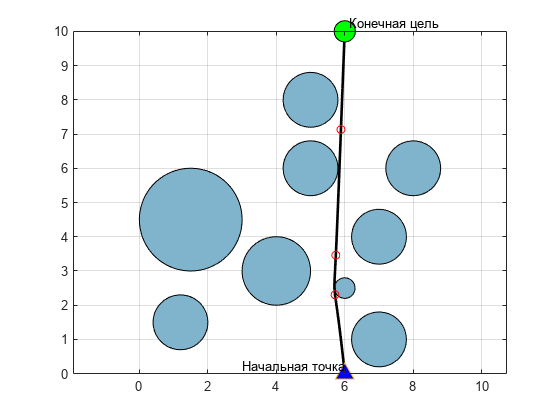


for it = 1:MaxIt
    
    for i = 1:nPop
        
        % x-часть
        
        % Обновление скорости
        particle(i).Velocity.x = w * particle(i).Velocity.x ...
            + c1 * rand(VarSize) .* (particle(i).Best.Position.x - particle(i).Position.x) ...
            + c2 * rand(VarSize) .* (GlobalBest.Position.x - particle(i).Position.x);
        
        % Ограничение скорости
        particle(i).Velocity.x = max(particle(i).Velocity.x, VelMin.x);
        particle(i).Velocity.x = min(particle(i).Velocity.x, VelMax.x);
        
        % Обновление положения
        particle(i).Position.x = particle(i).Position.x + particle(i).Velocity.x;
        
        % Зеркалирование скорости
        OutOfTheRange = (particle(i).Position.x < VarMin.x | particle(i).Position.x > VarMax.x);
        particle(i).Velocity.x(OutOfTheRange) = -particle(i).Velocity.x(OutOfTheRange);
        
        % Ограничение положения
        particle(i).Position.x = max(particle(i).Position.x, VarMin.x);
        particle(i).Position.x = min(particle(i).Position.x, VarMax.x);
        
        % y-часть
        
        % Обновление скорости
        particle(i).Velocity.y = w * particle(i).Velocity.y ...
            + c1 * rand(VarSize) .* (particle(i).Best.Position.y - particle(i).Position.y) ...
            + c2 * rand(VarSize) .* (GlobalBest.Position.y - particle(i).Position.y);
        
        % Ограничение скорости
        particle(i).Velocity.y = max(particle(i).Velocity.y, VelMin.y);
        particle(i).Velocity.y = min(particle(i).Velocity.y, VelMax.y);
        
        % Обновление положения
        particle(i).Position.y = particle(i).Position.y + particle(i).Velocity.y;
        
        % Зеркалирование скорости
        OutOfTheRange = (particle(i).Position.y < VarMin.y | particle(i).Position.y > VarMax.y);
        particle(i).Velocity.y(OutOfTheRange) = -particle(i).Velocity.y(OutOfTheRange);
        
        % Ограничение положения
        particle(i).Position.y = max(particle(i).Position.y, VarMin.y);
        particle(i).Position.y = min(particle(i).Position.y, VarMax.y);
        
        % Оценка
        [particle(i).Cost, particle(i).Sol] = CostFunction(particle(i).Position);
        
        % Обновление личного лучшего решения
        if particle(i).Cost < particle(i).Best.Cost
            
            particle(i).Best.Position = particle(i).Position;
            particle(i).Best.Cost = particle(i).Cost;
            particle(i).Best.Sol = particle(i).Sol;
            
            % Обновление глобального лучшего решения
            if particle(i).Best.Cost < GlobalBest.Cost
                GlobalBest = particle(i).Best;
            end
            
        end
        
    end
    
    % Обновление лучшей найденной стоимости
    BestCost(it) = GlobalBest.Cost;
    
    % Затухание инерционного веса
    w = w * wdamp;

    % Вывод информации о текущей итерации
    if GlobalBest.Sol.IsFeasible
        Flag = ' *';
    else
        Flag = [', Нарушение = ' num2str(GlobalBest.Sol.Violation)];
    end
    disp(['Итерация ' num2str(it) ': Лучшая стоимость = ' num2str(BestCost(it)) Flag]);
    
    % Построение решения
    figure(1);
    PlotSolution(GlobalBest.Sol, model);
    pause(0.01);    
end

disp(['Итерация ' num2str(it) ': Лучшая стоимость = ' num2str(BestCost(it)) Flag]);

Итерация 500: Лучшая стоимость = 10.0245 *


## Результаты

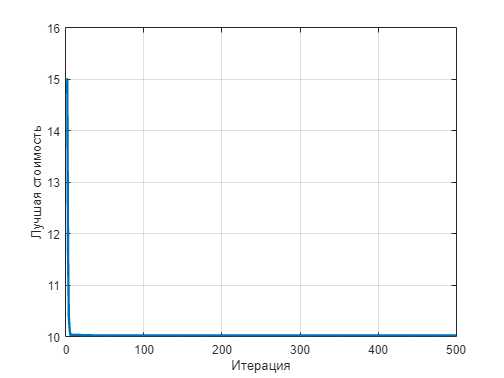

figure;
plot(BestCost, 'LineWidth', 2);
xlabel('Итерация');
ylabel('Лучшая стоимость');
grid on;